# ELABORATO 1 - INTEGRALE

# LO BRUTTO FABIO / MAIONE PAOLO

## DEFINIZIONE DEL PROBLEMA

Si vuole progettare un algoritmo in OpenMP per risolvere l'integrale definito tra `a` e `b` di una funzione $y=f\left(x\right)$ su p thread.

In particolare si utilizza l'infrastruttura S.C.o.P.E. per permette l'esecuzione del software in un ambiente parallelo. Tuttavia, a differenza degli elaborati MPI, il software è eseguibile anche su una macchina multicore locale.

## DESCRIZIONE DELL'ALGORITMO

In particolare l'algoritmo implementato nel file `elaborato_1.c`, consiste nell'elaborazione dell'integrale parziale in parallelo con la **formula trapezoidale composita ** sul sotto intervallo di ampiezza  $h=\frac{\left(b-a\right)}{\textrm{num}\underline{\;} \textrm{intervalli}}$

                                                              
$$T_{n+1} \left(f\right)=\frac{h}{2}\text{ }\left(f\left(a\right)+f\left(b\right)+2\text{ }\sum_{i=1}^{n} f\left(a+\mathrm{ih}\right)\right)$$
   

Questa formula è realizzata attraverso un ciclo for parallelizzato su p thread utilizzando le direttive e le clausole fornite da OpenMP.

Inoltre l'algoritmo progettato comprende anche il caso in cui il numero degli intervalli non è multiplo del numero di thread p a disposizione.

Si è scelto di misurare i tempi di esecuzione nel thread 0 (master) usando la primitiva` omp_get_wtime()` prima e dopo il calcolo parallelo scegliendo il minimo tra 3 misurazioni ripetute.

Infine, si osservi che i controlli di robustezza del software sono stati interamente delegati al master thread.

## INPUT, OUTPUT E CONDIZIONI DI ERRORE

- **Input**: la funzione $f$ da integrare, i due estremi dell'intervallo` a` e `b`, il numero di intervalli `num_intervalli.`

- **Output**: l'approssimazione dell'integrale definito tra `a` e `b` di $f$.

- **Condizioni di errore**: l'estremo `b` non deve essere minore di `a`, il numero di intervalli deve essere un intero positivo non minore del numero di thread.

## ESEMPIO DI FUNZIONAMENTO

Nell'immagine seguente vi è un esempio di funzionamento con p=8 thread, $f\left(x\right)=\frac{x}{x^2 +5}$ ,

con `a=0` e `b=1` e con `num_intervalli = 100000.`

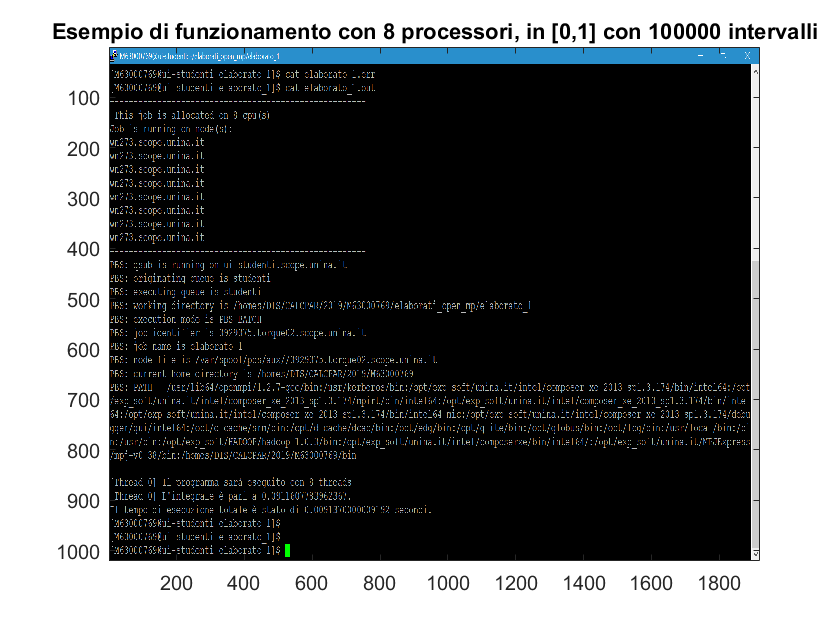

%esempio di funzionamento
funzionamento

## ESEMPI DI ERRORE

Nelle successivi immagini, invece, sono mostrati i messaggi di errore al verificarsi delle condizioni sopra citate.

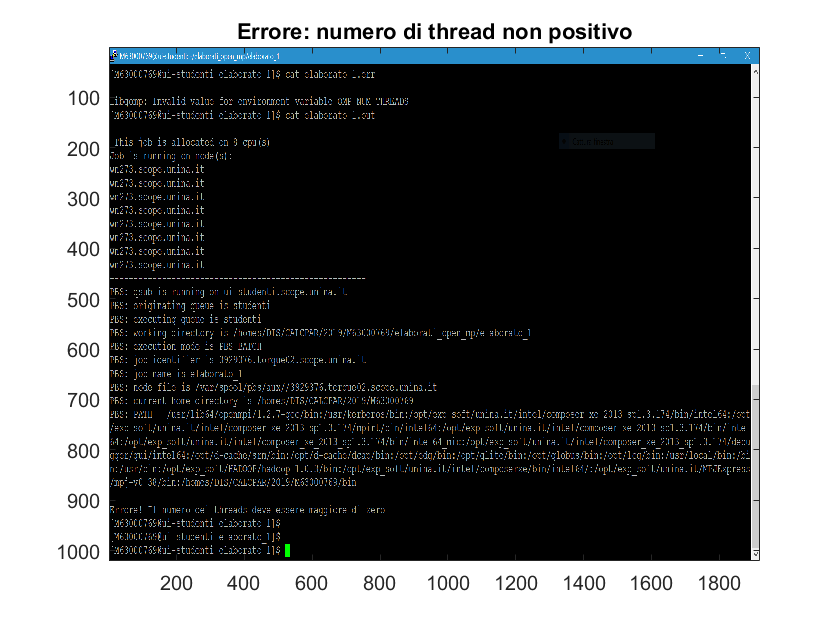

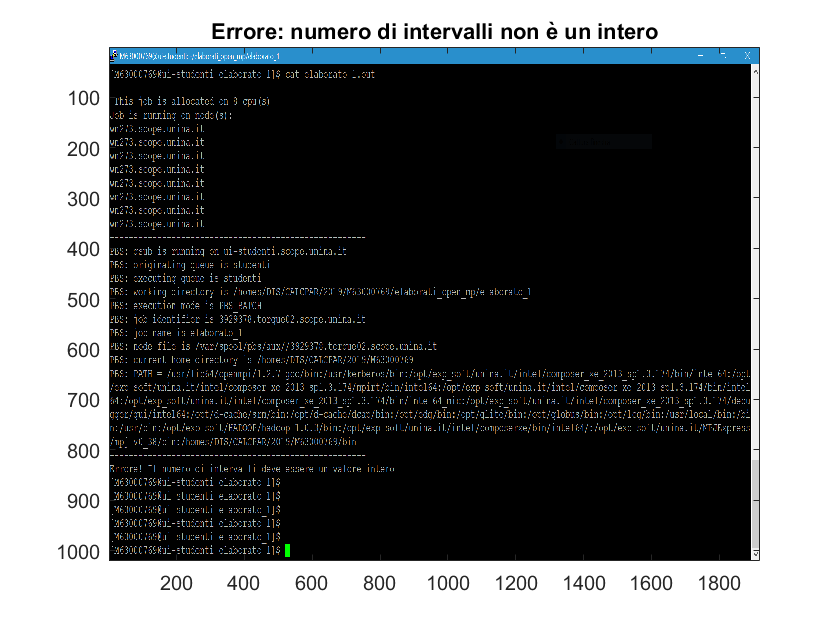

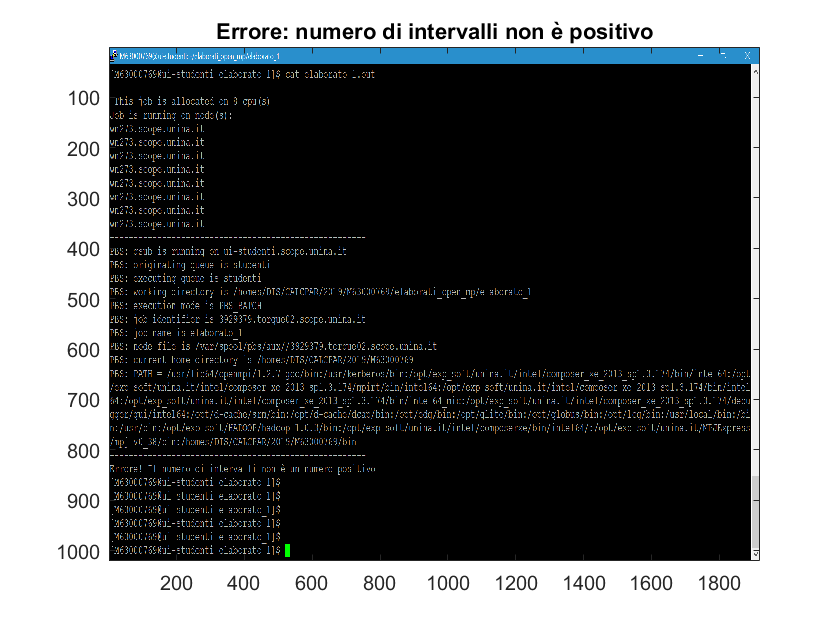

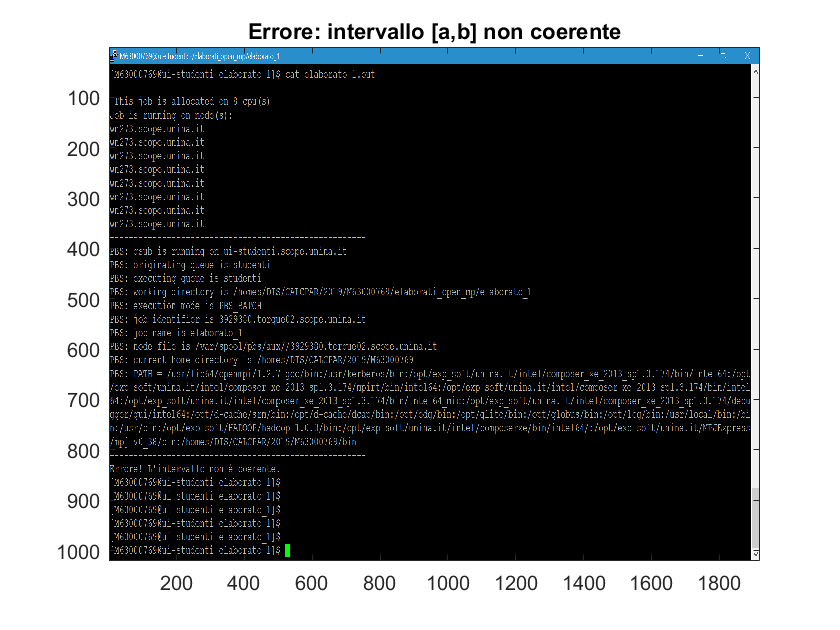

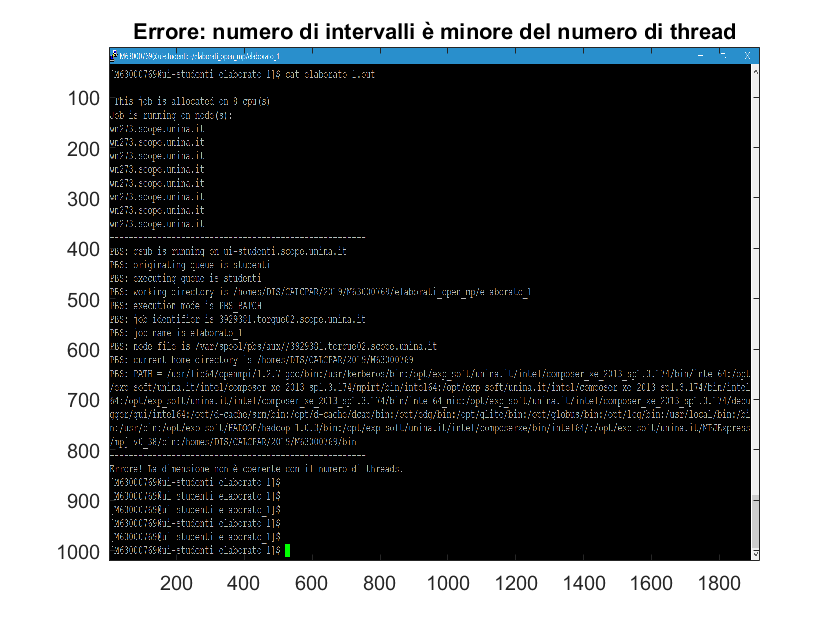

%un esempio per ciascuna condizione di errore
errori

## ANALISI DELLE PRESTAZIONI (T(p), S(p), E(p))

Di seguito per brevità si indicherà con p il numero di thread e con N il numero di intervalli.

## Tempo di esecuzione - T(p)

Si è scelto di misurare i tempi di esecuzione usando la primitiva` omp_get_wtime()` prima e dopo il calcolo parallelo.

Per ciascuna misurazione (al variare di N da 10k a 100M e al variare di p da 2 a 8) è stato considerato il minimo tra 3 esecuzioni ripetute, eseguite in momenti diversi.

Di seguito si riportano i risultati in forma di tabelle e grafici.

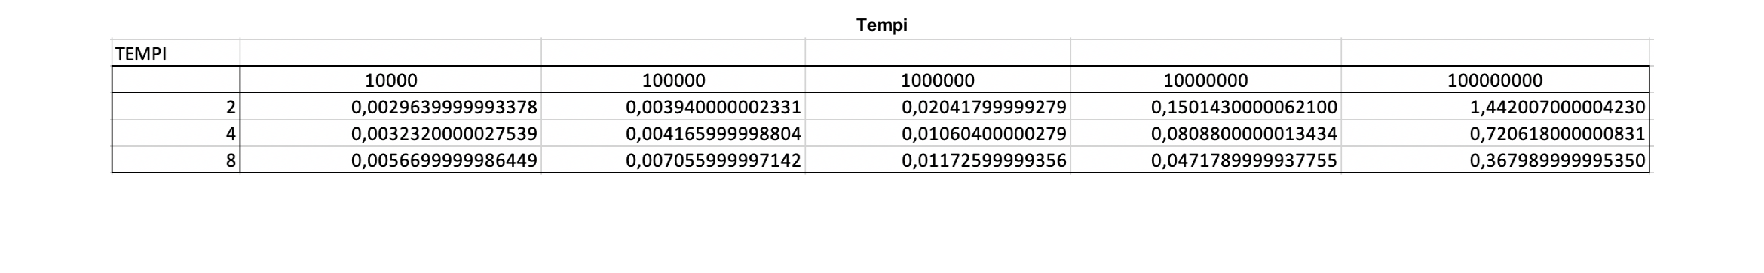

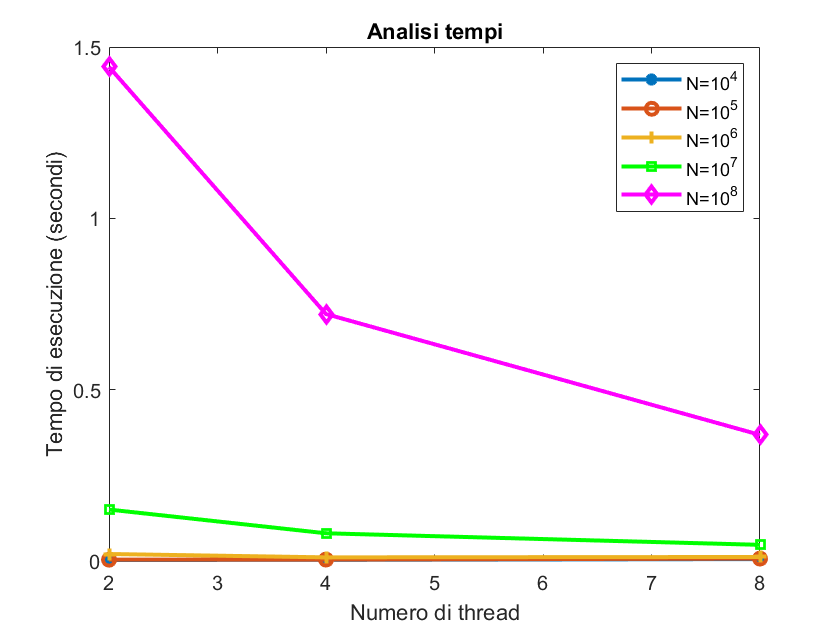

%esecuzione script per tabelle e grafici
tempi

Per considerazioni più di dettaglio su questi risultati si rimanda alla sezione Conclusioni.

## Speed up ed Efficienza - S(p) ed E(p)

Si è calcolato, inoltre, il tempo di riferimento `T(1)` che corrisponde al tempo di esecuzione su un processo single-thread.

A partire dai tempi misurati nella sezione precedente e da `T(1)` è stato calcolato lo speed-up al variare di N e p.

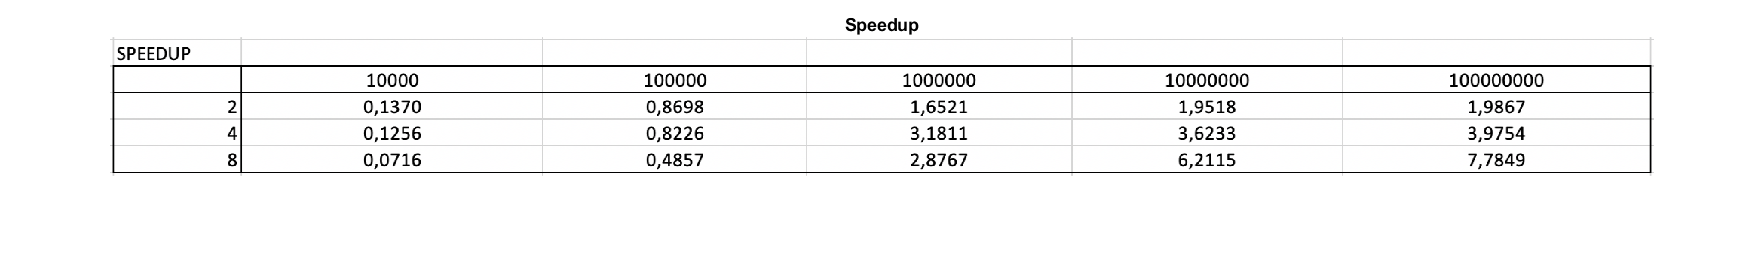

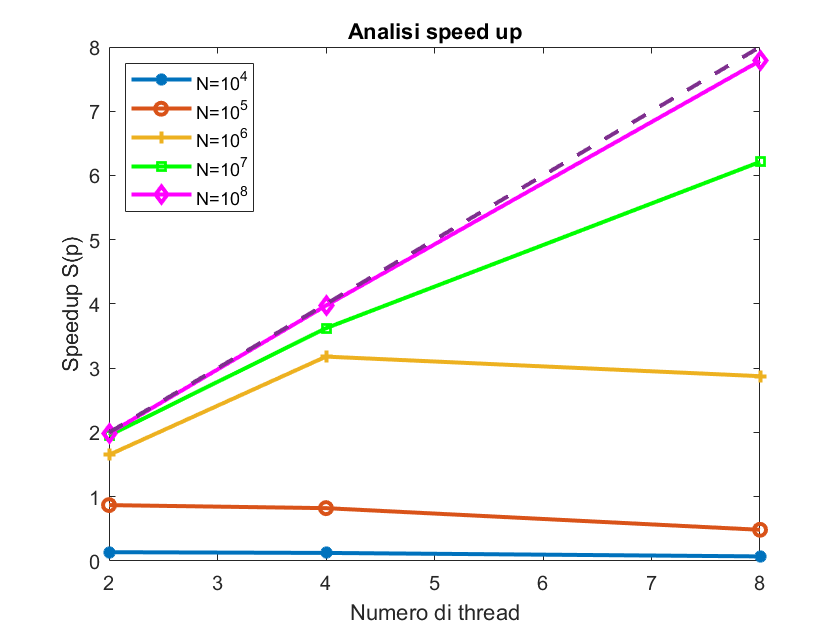

%esecuzione script per tabelle e grafici
speedup

Infine si è calcolata l'efficienza rapportando lo speed up S(p) al numero di thread p.

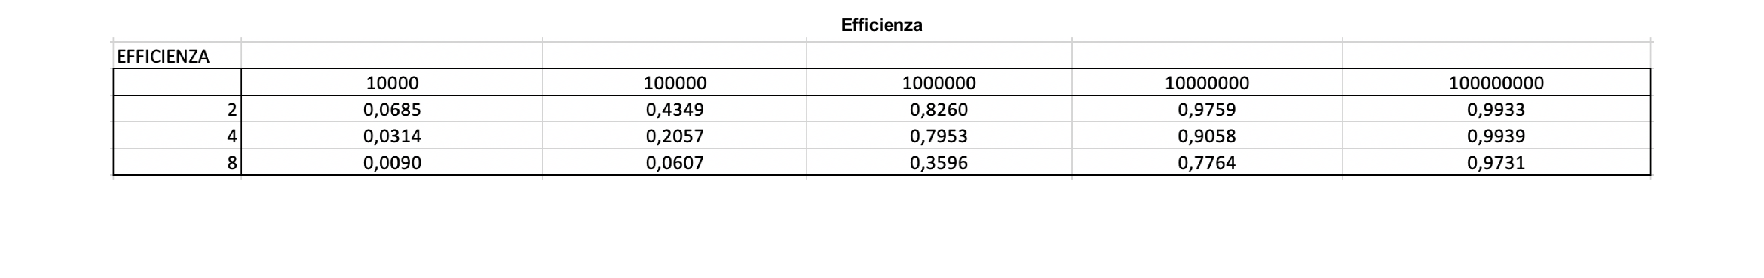

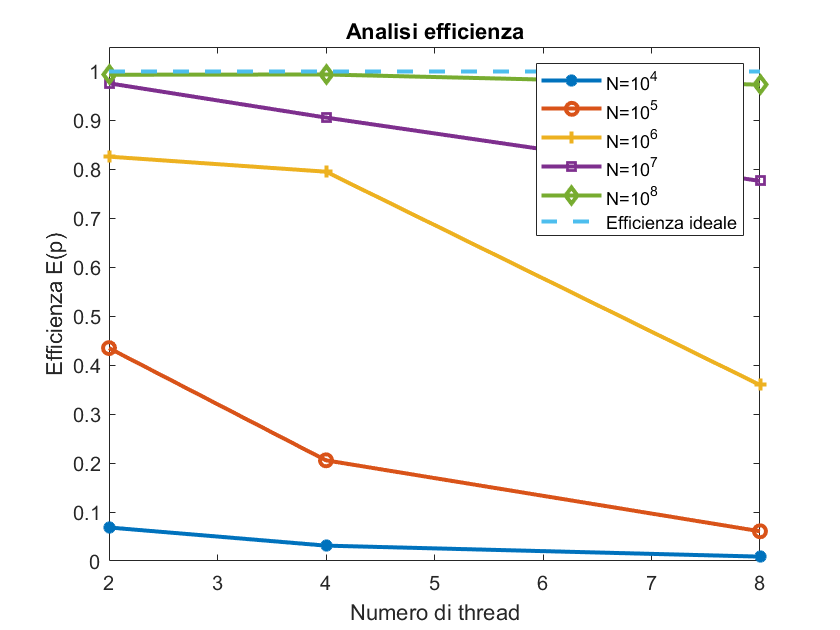

%esecuzione script per tabelle e grafici
efficienza

## Conclusioni

Dai grafici appena presentati si possono trarre alcune considerazioni.

Analizzando l'efficienza si nota come da N=${10}^4$ a N=${10}^7$ l'efficienza ottimale si ha per 2 thread. Nel caso N=${10}^4$ l'efficienza è estremamente bassa, probabilmente a causa del fatto che la creazione e la terminazione dei thread genera un enorme overhead rispetto alla dimensione del problema.

Invece nel caso di N=${10}^8$ l'ottimo è in corrispondenza di 4 thread.

Si possono fare ulteriori considerazioni notando che, per N fissato, l'efficienza peggiora dopo un certo valore di p (ciò verifica sperimentalmente la legge di Amdahl), e che, in generale, all'aumentare sia di N che di p, l'efficienza migliora (verificando la legge di Gustafson).

Analoghe considerazioni per i tempi e lo speedup.

## ANALISI DELL' ACCURATEZZA

Confrontando i risultati ottenuti sul cluster Scope e quelli ottenuti su MATLAB si ottengono i seguenti errori relativi. I livelli di accuratezza sono stati misurati fissando a 8 il numero di thread, e facendo variare la dimensione del problema `num_intervalli`. Gli estremi di integrazione scelti sono `a=0 , b=5`.

Per i test è stata usata la seguente funzione integranda:  


$$f\left(x\right)=1+\mathrm{sin}\left(10x\right)\ast \frac{x}{x^2 +5}$$


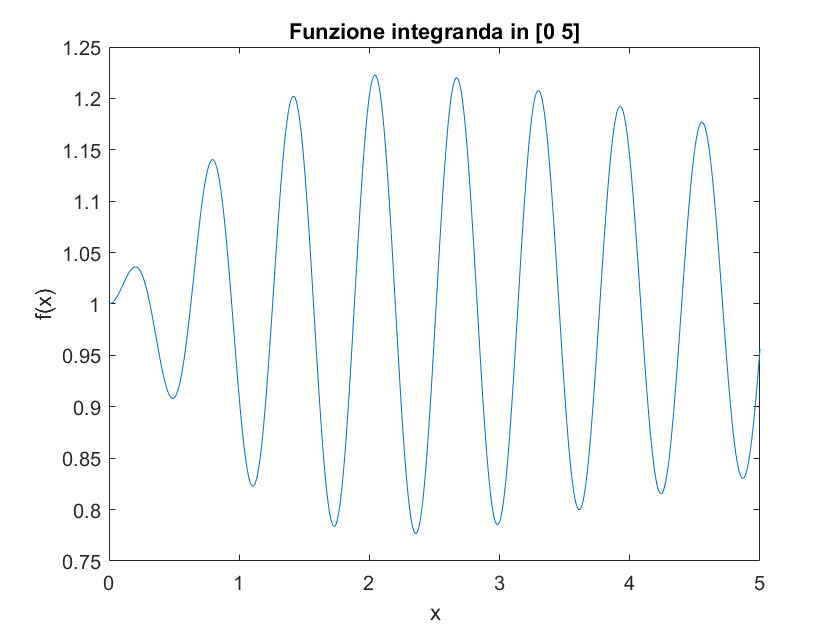

%grafico della funzione integranda
grafico

%esecuzione script per i test di accuratezza
accuratezza

F = function_handle with value:
    @(x)1+sin(10.*x).*(x./(x.^2+5))


risultato_matlab =    4.983979125364205


err_rel_10k_intervalli =      1.259469664462556e-08


err_rel_100k_intervalli =      5.915098092282934e-09


err_rel_1M_intervalli =      5.848306046909409e-09


err_rel_10M_intervalli =      5.847643830851800e-09


err_rel_100M_intervalli =      5.847607833100552e-09
